Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x-2).^2.*sin(12*x-4);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = lhsdesign(500,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2)+means.linear(6)

ma =   const with properties:

         meanz: {[1×1 means.const]  [1×1 means.linear]}
        coeffs: {[2]  [6]}
    operations: {'+'}


a = kernels.Matern52(1,0.2)*kernels.EQ(1,0.4).periodic(1,2) + kernels.RQ(0.1,0.3);

a.signn = 0.5;

Z = VGP(ma,a,linspace(0,1,5)');

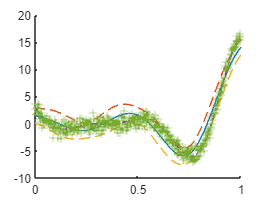

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
plot(xx,ys)
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')

tic
[Z2,LL] = Z1.train();

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 29.7425 +/- 0.843982 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 28.7142 +/- 0.770675 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 50.8234 +/- 10.3335 (mean +/- SEM from 10 samples).



toc

Elapsed time is 37.696864 seconds.


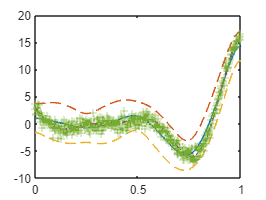

[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')


for i = 1:5
    xn = bads(@(x) Z2.newXuDiff(x),rand(),0,1);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -1.92031               1                              Uncertainty test
     0           3        -3.14982               1            Initial mesh      
     1           4        -3.14982             0.5             Refine grid      Train (failed)
     2           6         -5.0071             0.5    Successful search (ES-wcm)      
     2           7        -5.24898             0.5    Incremental search (ES-wcm)      
     2          12        -5.73508               1         Successful poll      
     3          15        -5.73508             0.5             Refine grid      
     4          16        -5.74044             0.5    Incremental search (ES-wcm)      
     4          17        -5.74062             0.5    Incremental search (ES-wcm)      
     4          18         -5.7408             0.5    Incremental sea

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -7.85735               1                              Uncertainty test
     0           3        -7.85735               1            Initial mesh      
     1           4        -7.85735             0.5             Refine grid      Train (failed)
     2           9        -7.85735            0.25             Refine grid      
     3          14        -7.85735           0.125             Refine grid      Train
     4          15        -7.86583           0.125    Incremental search (ES-ell)      
     4          16        -7.86583           0.125    Incremental search (ES-wcm)      
     4          19        -7.86583          0.0625             Refine grid      
     5          24        -7.86583         0.03125             Refine grid      Train
     6          29        -7.86583        0.015625             Refine gr

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.561466               1                              Uncertainty test
     0           3       -0.561466               1            Initial mesh      
     1           4       -0.561466             0.5             Refine grid      Train (failed)
     2           6        -1.66277             0.5    Successful search (ES-wcm)      
     2           8        -1.77769             0.5    Incremental search (ES-wcm)      
     2           9        -1.79045             0.5    Incremental search (ES-wcm)      
     2          10         -1.7996             0.5    Incremental search (ES-wcm)      
     2          11        -4.88979               1         Successful poll      
     3          15        -4.88979             0.5             Refine grid      Train
     4          18        -4.88979            0.25             R

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.111301               1                              Uncertainty test
     0           3         -2.1539               1            Initial mesh      
     1           4         -2.1539             0.5             Refine grid      Train (failed)
     2           9         -2.1539            0.25             Refine grid      
     3          10        -2.18367            0.25    Incremental search (ES-wcm)      
     3          11        -2.18422            0.25    Incremental search (ES-wcm)      
     3          12        -2.18428            0.25    Incremental search (ES-wcm)      
     3          14        -2.18428           0.125             Refine grid      Train
     4          15        -2.19185           0.125    Incremental search (ES-wcm)      
     4          16         -2.1921           0.125    Increment

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.811989               1                              Uncertainty test
     0           3       -0.811989               1            Initial mesh      
     1           4       -0.811989             0.5             Refine grid      Train (failed)
     2           8       -0.877981            0.25             Refine grid      
     3           9         -1.1861            0.25    Successful search (ES-ell)      
     3          16         -1.1861           0.125             Refine grid      Train
     4          17         -1.1864           0.125    Incremental search (ES-ell)      
     4          18        -1.18644           0.125    Incremental search (ES-wcm)      
     4          19        -1.18645           0.125    Incremental search (ES-ell)      
     4          21        -1.18645          0.0625             R

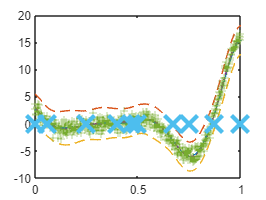


[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train();

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 26.0246 +/- 0.419121 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 24.2408 +/- 0.543741 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [3 4 5 6].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 25.0956 +/- 0.765237 (mean +/- SEM from 10 samples).



toc

Elapsed time is 24.138975 seconds.


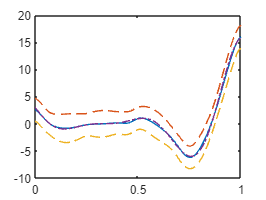


[ys,sig] = Z3.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')